load("_test_folder\34A_zscored.mat");
load("_test_folder\analysisstruct_concat.mat");

signal = data.channel_470;

membership = analysisstruct_concat.annot_reordered{end,end};
clusterIDs = analysisstruct_concat.sorted_clust_ind(:);
pts = analysisstruct_concat.zValues(membership==clusterIDs(1),:);    % z-values for cluster k
frame_idx = analysisstruct_concat.frames_with_good_tracking(1);


% check the cluster position


% 
channel = 1;

cluster_scores = gather_channel_values(clustered_v, channel);

% get the signal_mean of each cluster
scores = cellfun(@mean, cluster_scores)

scores =    -1.1518   -0.3054   -0.0313    0.3454   -0.2848   -0.4638    0.3841    0.1172    0.4715    0.7070   -0.7631    2.8503    0.5334   -0.9646   -1.9632   -0.8993   -0.7536    0.0940    0.0954   -0.4802   -1.5584    0.6471    0.2087   -0.3310   -0.1674    0.2181   -0.7444   -0.6842   -0.7955   -0.3351    0.0449   -0.2679   -0.1182    0.0201    0.4013   -0.2323    0.0577   -0.6190    0.5135   -0.1597   -1.1263   -0.4088    0.4780   -0.0204    0.2436    0.5241    0.9241   -0.3687   -0.5488   -0.3419


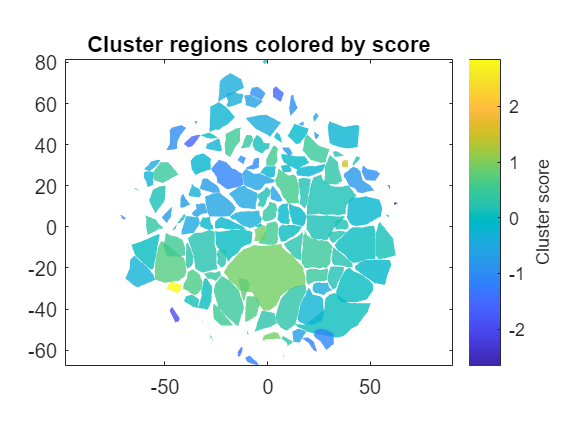


fill_the_cluster(clustered_z, scores)

cluster_num = numel(clustered_z)

cluster_num = 126

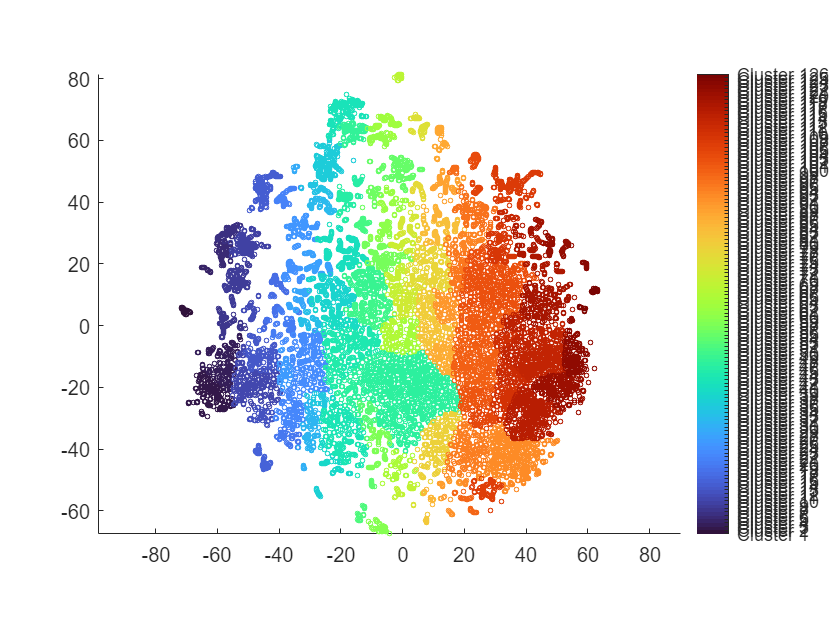

cmap        = turbo(cluster_num);

figure; hold on
for i = 1:cluster_num
    z_values_in_cluster = clustered_z{i};
    scatter(z_values_in_cluster(:, 1), z_values_in_cluster(:, 2), 5, cmap(i,:));
end
axis equal

colormap(turbo(cluster_num));     % same colormap you prepared
caxis([1 cluster_num]);           % map 1..cluster_num across the colormap

cb = colorbar;                    % add the bar
cb.Ticks = 1:cluster_num;         % one tick per cluster
cb.TickLabels = compose('Cluster %d',1:cluster_num);  % optional labeling

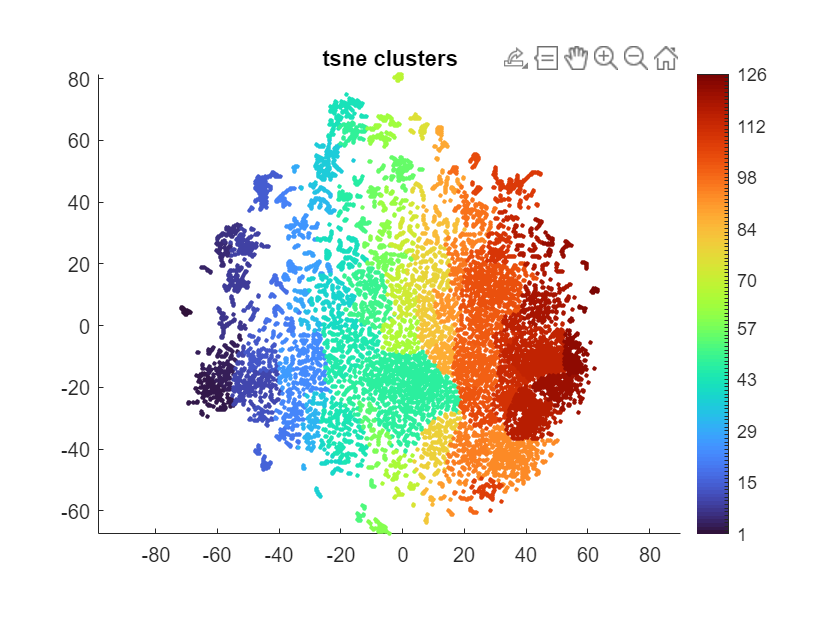

cluster_num  = numel(clustered_z);

% -------- concatenate all XY points vertically --------
allXY = vertcat(clustered_z{:});    % N-by-2

% -------- build a cluster-ID column of the same length --------
cluster_sizes = cellfun(@(c) size(c,1), clustered_z);   % points per cluster
clusterID     = repelem((1:cluster_num).', cluster_sizes);   % N-by-1

% -------- plot --------
figure
scatter(allXY(:,1), allXY(:,2), 5, clusterID, 'filled');
axis equal
colormap(turbo(cluster_num));
caxis([1 cluster_num]);

Ntick = 10;                                    % 目标显示 10 个
showTicks = round(linspace(1, cluster_num, Ntick));

cb = colorbar;
cb.Ticks = 1:cluster_num;
cb.TickLabels = repmat({''},1,cluster_num);
cb.TickLabels(showTicks) = compose('%d', showTicks);

title('tsne clusters')

% get all the signal segments and plot them together
channel = 1;
cluster_scores = gather_channel_values(clustered_v, channel);
scores = cellfun(@mean, cluster_scores)

scores =    -1.1518   -0.3054   -0.0313    0.3454   -0.2848   -0.4638    0.3841    0.1172    0.4715    0.7070   -0.7631    2.8503    0.5334   -0.9646   -1.9632   -0.8993   -0.7536    0.0940    0.0954   -0.4802   -1.5584    0.6471    0.2087   -0.3310   -0.1674    0.2181   -0.7444   -0.6842   -0.7955   -0.3351    0.0449   -0.2679   -0.1182    0.0201    0.4013   -0.2323    0.0577   -0.6190    0.5135   -0.1597   -1.1263   -0.4088    0.4780   -0.0204    0.2436    0.5241    0.9241   -0.3687   -0.5488   -0.3419


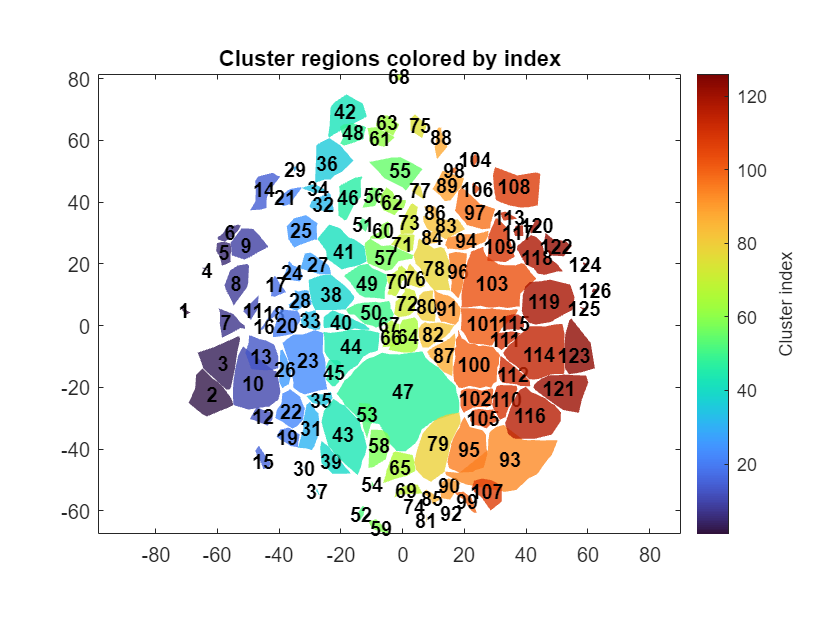


plot_cluster(clustered_z)

title()
